** To get the output, run each section.

Read and display image

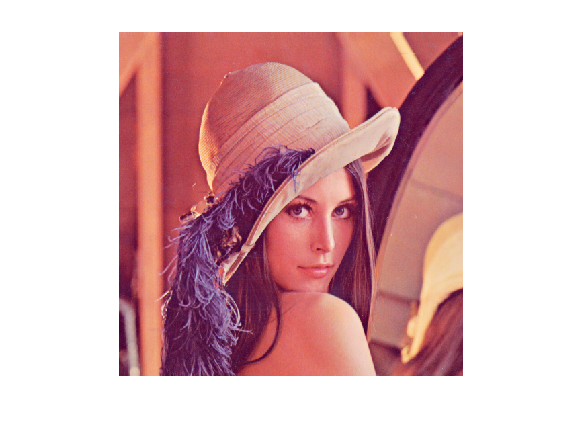

im = imread('image1.png');
imshow(im)

imwrite(im, 'res1.png');

Covert color image into HSV and display each channel

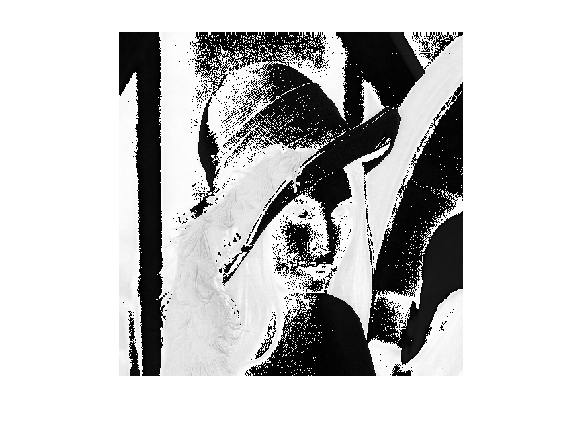

hsv = rgb2hsv(im); 

imshow(hsv(:, :, 1))

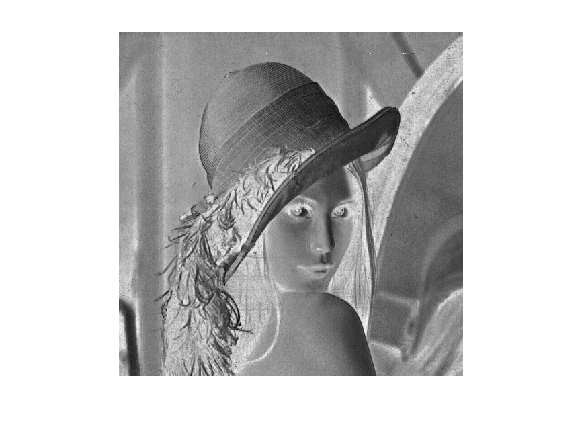

imwrite(hsv(:, :, 1), 'hsv1.png');

imshow(hsv(:, :, 2))

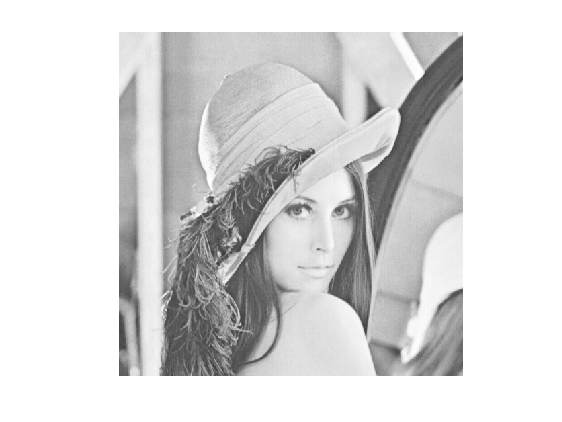

imwrite(hsv(:, :, 2), 'hsv2.png');

imshow(hsv(:, :, 3))

imwrite(hsv(:, :, 3), 'hsv3.png');

Enlarge and crop image 

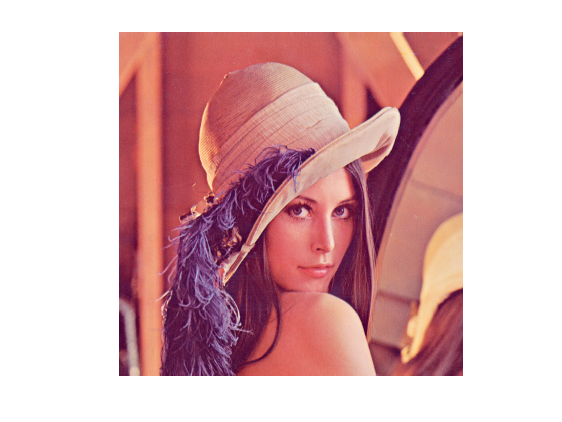

re_img = imresize(im, 2.0); % Enlarge image by 2 times 
imshow(re_img)

imwrite(re_img, 're.png');

cr_img = imcrop(re_img,[0 0 1024 1024]); % Crop image to original
imshow(cr_img)

imwrite(cr_img, 'cr.png');

Convert color image into grayscale

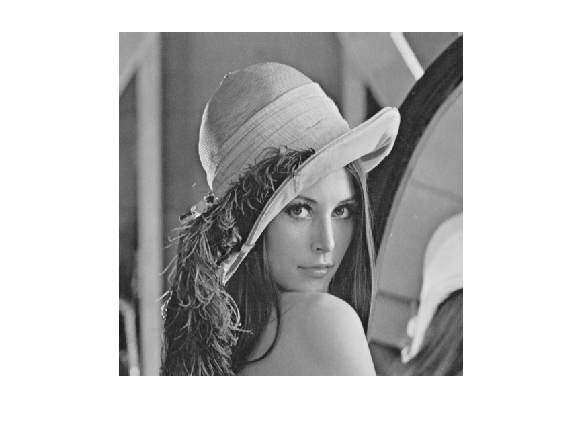

gray = rgb2gray(im);
imshow(gray)

imwrite(gray, 'gray.png');

Generate and display histogram

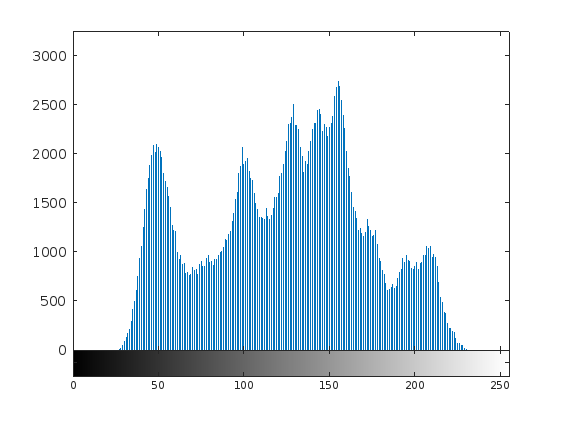

hfig = figure; imhist(gray)
saveas(hfig, 'hist.png');

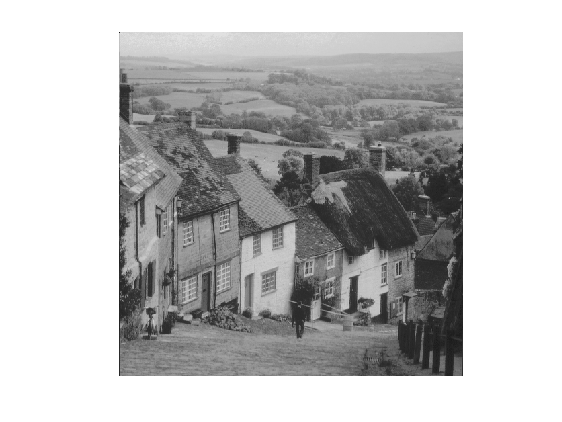

inp1 = imread('image1.png');
inp2 = imread('image2.png');
out = histMatching(inp1, inp2); % Calling the histogram matching function
imshow(out)

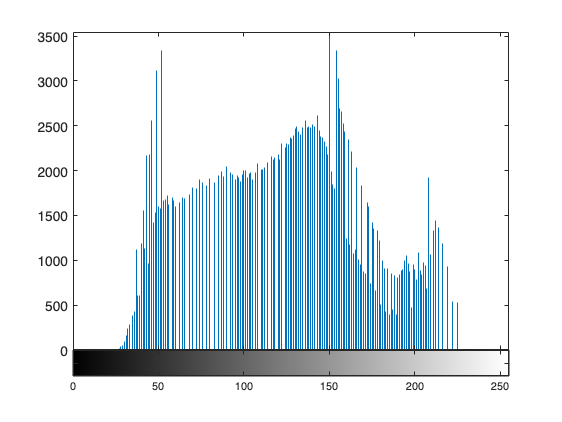

imhist(out)

imwrite(out, 'matced.png');

Function for histogram matching

function out = histMatching(iMat1, iMat2)
    im1 = im2gray(iMat1); % color conversion
    im2 = im2gray(iMat2); % color conversion
    ref = imhist(im1); % reference histogram
    out = histeq(im2, ref);
end